# Lösen des allgemeinen linearen Ausgleichsproblems über SVD

Sei    $A=\pmatrix{1&3 & 2 \cr 2&-1 & 4  \cr 1&2 &2}$. Diese Matrix hat Rang 2. Für $b \in \mathbb R^3$ betrachten  wir das allgemeine lineare Ausgleichsproblem

              $\min_{x \in \mathbb R^3} \|Ax-b\|_2$  mit  $\|x\|_2$ minimal.

Die Lösung dieses Problems lässt sich mit der Singulärwertzerlegung als

      
$$x= A^\dagger b= \sum_{j=1}^2 \sigma_j^{-1} (b^T u_j) v_j$$


darstellen (siehe Buch).

# Aktivität:

Wählen Sie  ein $b \in \mathbb R^3$, mit $\|b\|_\infty \leq 2$. Beispiele: $b=(0,-2,-1)^T$, $b=(0.1,2-1)^T$,  $b=(2,-1,0)^T$

A=makeA;
A

A =      1     3     2
     2    -1     4
     1     2     2


b= [0.1;-2;-1]

b =     0.1000
   -2.0000
   -1.0000


[U,S,V]= svd(A)

U =    -0.5490    0.6044   -0.5774
   -0.6779   -0.7261   -0.1155
   -0.4890    0.3280    0.8083


S =     5.6956         0         0
         0    3.4000         0
         0         0    0.0000


V =    -0.4203   -0.1529    0.8944
   -0.3419    0.9398    0.0000
   -0.8405   -0.3058   -0.4472


Es werden nacheinander 

     $r=U^Tb=(b^Tu_1)u_1 +(b^Tu_2)u_2 +(b^T u_3)u_3,
$    (Zerlegung von $b$ in der $U$-Basis in $\mathbb{R}^3$)

     $s= \Sigma^\dagger r,$    (Stauchung/Streckung entlang der Koordinatenachsen)

     $Vs=\sum_{j=1}^2 s_j v_j = A^\dagger b$    (Darstellung $x=A^\dagger b$ in der $v$-Basis in $\mathbb R^3$)

berechnet und visualisiert.

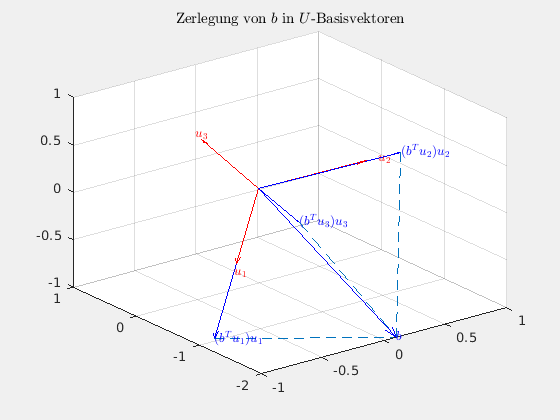

r=ZerlegungU(U,b);

fprintf('\n Vektor r=U^T*b: \n');


 Vektor r=U^T*b: 


r

r =     1.7898
    1.1846
   -0.6351


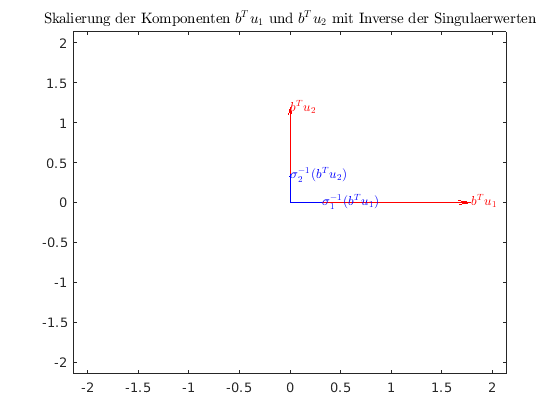

s=Skalierung(S,r);

fprintf('\n Vektor s: \n');


 Vektor s: 


s

s =     0.3142
    0.3484


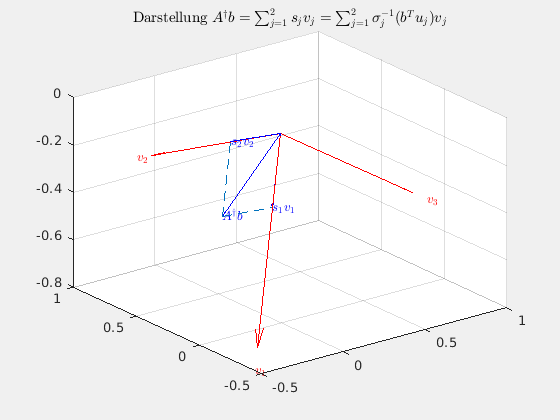

Loesungx=ZerlegungV(V,s);

fprintf('\n Vektor V*s: \n');


 Vektor V*s: 


Loesungx

Loesungx =    -0.1853
    0.2200
   -0.3707


# Aktivität:

Schauen Sie sich die geometrischen Darstellungen der einzelnen Schritte genau an.

function A=makeA
       A=[1 3 2; 2 -1 4; 1 2 2];
end

function r=ZerlegungU(U,b)
    figure(1);
      rotate3d on;
      axis equal;
      o= [0 0 0];
      quiver3(o,o,o, U(1,:),U(2,:),U(3,:), "Color","red");
    text( U(1,:),U(2,:),U(3,:),  {'$u_1$';'$u_2$';'$u_3$'}, "Interpreter","latex",...
        "Color","red");
    hold on;
    r1=b'*U(:,1); r2=b'*U(:,2);r3=b'*U(:,3);
    r=[r1;r2;r3];
    r1u=r1*U(:,1); r2u=r2*U(:,2); r3u=r3*U(:,3); 
     quiver3(0,0,0,r1u(1),r1u(2),r1u(3),0,"Color","blue");
     text(r1u(1),r1u(2),r1u(3),{'$(b^Tu_1)u_1$'}, "Interpreter","latex","Color","blue");
     quiver3(0,0,0,r2u(1),r2u(2),r2u(3),0,"Color","blue");
     text(r2u(1),r2u(2),r2u(3),{'$(b^Tu_2)u_2$'}, "Interpreter","latex","Color","blue");
     quiver3(0,0,0,r3u(1),r3u(2),r3u(3),0,"Color","blue");
     text(r3u(1),r3u(2),r3u(3),{'$(b^Tu_3)u_3$'}, "Interpreter","latex","Color","blue");
    quiver3(0,0,0,b(1),b(2),b(3),0,"Color","blue");
     text(b(1),b(2),b(3),{'$b$'}, "Interpreter","latex","Color","blue");
     line([r1u(1);b(1)], [r1u(2);b(2)],[r1u(3);b(3)],'LineStyle','--');
     line([r2u(1);b(1)], [r2u(2);b(2)],[r2u(3);b(3)],'LineStyle','--');
     line([r3u(1);b(1)], [r3u(2);b(2)],[r3u(3);b(3)],'LineStyle','--');
      title('Zerlegung von $b$ in $U$-Basisvektoren','Interpreter','latex');
   hold off;
end

function Sr=Skalierung(S,r)
   figure(2);
  Sr=[S(1,1)^(-1)*r(1);S(2,2)^(-1)*r(2)];
  quiver(0,0,r(1),0,0,"Color","red");
  text(r(1),0,{'$b^Tu_1$'}, "Interpreter","latex","Color","red");
  hold on;
  s1=1.2*norm([Sr;r],'inf'); 
  axis([-s1 s1 -s1 s1]); 
  quiver(0,0,0,r(2),0,"Color","red");
  text(0,r(2),{'$b^Tu_2$'}, "Interpreter","latex","Color","red");
  quiver(0,0,Sr(1),0,0,"Color","blue");
  text(Sr(1),0,{'$\sigma_1^{-1}(b^Tu_1)$'}, "Interpreter","latex","Color","blue");
  quiver(0,0,0,Sr(2),0,"Color","blue");
  text(0,Sr(2),{'$\sigma_2^{-1}(b^Tu_2)$'}, "Interpreter","latex","Color","blue");
  title('Skalierung der Komponenten $b^Tu_1$ und $b^Tu_2$ mit Inverse der Singulaerwerten','Interpreter','latex');
  hold off;
end
    

function y=ZerlegungV(V,s)
     figure(3);
      rotate3d on;
      s1=1.2*norm(s,'inf'); 
      axis([-s1 s1 -s1 s1 -s1 s1]); 
      o= [0 0 0];
      quiver3(o,o,o, V(1,:),V(2,:),V(3,:), "Color","red");
    text( V(1,:),V(2,:),V(3,:),  {'$v_1$';'$v_2$';'$v_3$'}, "Interpreter","latex",...
        "Color","red");
    hold on;
    y1=s(1)*V(:,1); y2=s(2)*V(:,2);
     quiver3(0,0,0,y1(1),y1(2),y1(3),0,"Color","blue");
     text(y1(1),y1(2),y1(3),{'$s_1v_1$'}, "Interpreter","latex","Color","blue");
     quiver3(0,0,0,y2(1),y2(2),y2(3),0,"Color","blue");
     text(y2(1),y2(2),y2(3),{'$s_2v_2$'}, "Interpreter","latex","Color","blue");
   y=V*[s;0];
    quiver3(0,0,0,y(1),y(2),y(3),0,"Color","blue");
     text(y(1),y(2),y(3),{'$A^\dagger b$'}, "Interpreter","latex","Color","blue");
     line([y(1);y1(1)], [y(2);y1(2)],[y(3);y1(3)],'LineStyle','--');
      line([y(1);y2(1)], [y(2);y2(2)],[y(3);y2(3)],'LineStyle','--');
      title('Darstellung $A^{\dagger}b=\sum_{j=1}^2 s_j v_j=\sum_{j=1}^2 \sigma_j^{-1} (b^T u_j)v_j$','Interpreter','latex');
   hold off;
end